% This code was generated via ChatGPT 5.4 ("extended thinking").


## F-16A Level 1 Sizing Analysis — Class-Based Example

% This live script performs a Level 1 sizing pass for the F-16A example using
% the toolkit classes supplied with the project.
%
% Main objects used:
%   * AircraftDesign
%   * GeometryLevel1
%   * AeroLevel1
%   * PropulsionLevel1
%   * WeightLevel1
%   * MissionAnalysisLevel1
%   * ConstraintAnalysisClass
%   * Requirements
%   * SizingClassLevel1
%
% The script assumes the corresponding class files, import utilities, design
% workbook, requirements table, constraints table, and mission profile are on
% the MATLAB path.

clear;

%% Project setup
% Set this to the folder containing your classes, import utilities, design
% spreadsheet/workbook, requirements file, constraints file, and mission data.
projectRoot = pwd;
addpath(projectRoot);

% Change these names only if your local files use different names.
designName       = "F-16A Block 50";
requirementsName = "Requirements";
constraintsName  = "Constraints";
missionName      = "CAP";


## Create the aircraft design object

% AircraftDesign is the project-level object. It imports the design geometry,
% fuselage data, propulsion data, weight data, general aircraft data, and
% requirements reference.

design = AircraftDesign( ...
     designName, ...
     RequirementsName = requirementsName, ...
     ConstraintsName  = constraintsName, ...
     AutoLoad         = true);


% Keep the constraints filename explicit in case the design constructor was
% given a blank or nonstandard value.
if strlength(string(design.constraints_filename)) == 0
     design.constraints_filename = constraintsName;
end

disp("AircraftDesign object created:")

AircraftDesign object created:


disp(design)

  AircraftDesign with properties:

                     Name: "F-16A Block 50"
                     geom: [1×1 struct]
                  general: [1×1 struct]
               propulsion: [1×1 struct]
          propulsion_type: "low bpr turbofan"
                n_engines: []
                 CivOrMil: []
                     role: []
                  weights: [1×1 struct]
                     type: "Jet fighter"
              wing_config: []
              tail_config: []
            fuselage_type: []
               nose_shape: []
             requirements: [1×1 struct]
    requirements_filename: []
     constraints_filename: "Constraints"
            WeightResults: []
              AeroResults: []
        PropulsionResults: []
           internalvolume: []


## Build the Level 1 analysis objects

% These objects are intentionally lower-fidelity than the Level 3 versions.
% They rely on historical estimates, tabulated assumptions, and simple mission
% weight fractions/Breguet-style estimates.


% Compute required constraints
% constraint_obj.constraint_analysis;

## Weight

weight_obj       = F16WeightLevel1(design);

## Geometry

geometry_obj     = F16GeometryLevel1(design, weight_obj);

## Aerodynamics object

Initialize some things for the Aero object

aero_obj         = F16AeroLevel1("jet fighter", geometry_obj, weight_obj);
aero_obj.Cf = AeroLevel1.get_Cf("air force fighter", 1);
aero_obj.CL_minD = 0.02843; % Hardcoded from Brandt

## Propulsion

propulsion_obj   = F16PropulsionLevel1(design);

## Mission

mission_obj      = F16MissionAnalysisLevel1(missionName);

## Constraints

Build the constraints.

constraint_obj   = F16ConstraintAnalysis();
% Need to update the aerodynamic constraints for each given constraint
% (altitude, mach number)

% Get table of state vectors (mach number, altitude) for each constraint
% (constraint name)
constraints_table = Import_Constraints(constraintsName);

constraints_length = length(constraints_table.Altitude_ft_)

constraints_length = 8


% Load up miscellaneous constraints
beta = constraints_table.W_Wto;
n = constraints_table.n;
mu = constraints_table.SurfaceFrictionCoefficient_mu_;
Ps = constraints_table.PS_ft_s_;
distance = constraints_table.Distance_ft_;

% Clean up inputs before things get messy
Ps(isnan(Ps)==1)=0;
n(isnan(n)==1)=0;
distance(isnan(distance)==1)=0;
mu(isnan(mu)==1)=0;


% Get the Mach number and altitude
M = constraints_table.MachNumber;
h_alt = constraints_table.Altitude_ft_;
state_vector = [M, h_alt];

% Set up geometry stuff
AR = geometry_obj.mainwings.AR;
LE_sweep_deg = geometry_obj.mainwings.LE_sweep;
Cf = aero_obj.Cf; % Compute this
S_wet = geometry_obj.get_design_S_wet("jet fighter", weight_obj.W_TO_guess);
S_ref = geometry_obj.mainwings.S_ref;
e_osw = aero_obj.e_osw;
T_SL_dry = propulsion_obj.T_SL_dry;
T_SL_wet = propulsion_obj.T_SL_wet;
gamma = 1.4;

W_S = constraint_obj.Wto_S_range;

% Get density at sea level
[T, a, P, rho_SL] = atmosisa(0);

% Convert rho_SL to slugs
rho_SL = rho_SL*0.00194032033; % Convert from kg/m^3 -> imperial units

for i=1:constraints_length
     current_constraint = constraints_table.Row{i}
     AB_percent = constraints_table.AB_(i);

     M = state_vector(i,1);
     h_alt = state_vector(i,2);
     newstatevector = [M, h_alt];

     % Get density at current altitude
     [T, a, P, rho] = atmosisa(h_alt*0.3048);

     % Convert rho to slugs
     rho = rho*0.00194032033; % Convert from kg/m^3 -> imperial units

     % Convert a to ft/s
     a = a*3.2808399;

     if isnan(AB_percent)==true
          AB_percent = 1.0;
     elseif (AB_percent > 1.0)
          AB_percent = AB_percent/100;
     elseif (0.0 < AB_percent < 1.0)
          % Do nothing
     else
          error("Error handler.") % Just in case something weird happens.
     end

     % This thing breaks for "takeoff" and "landing" segments.
     % Need takeoff/landing velocity for computations (CD0, alpha,
     % alpha_dry/wet). To get that velocity, I need the weight. To get the
     % weight, I need the velocity... I can start with the guess weight.
     if (current_constraint == "Takeoff")
          % Do takeoff calculations
          % V = 168; % Hardcoded takeoff velocity (ft/s)
          for k=1:length(W_S)
               V_stall = AeroUtils.V_stall(W_S(k), aero_obj.CL_max_TO, rho)
               V_TO = 1.2*V_stall;
               M_TO = V_TO./a;

               takeoff_statevector = [M_TO, h_alt];

               [K1, K2] = aero_obj.get_K(AR, e_osw, M_TO, LE_sweep_deg, aero_obj.CL_minD);
               [e_osw, CD0, V, q] = constraint_obj.get_aero_constraints(takeoff_statevector, e_osw, Cf, S_wet, S_ref)

               [alpha, alpha_dry, alpha_wet] = constraint_obj.get_thrust_constraints(takeoff_statevector, T_SL_dry, T_SL_wet, gamma, AB_percent, propulsion_obj)

               aero_constraints_takeoff(k, :) = [e_osw, K1, K2, CD0, V_TO, q];
               thrust_constraints_takeoff(k, :) = [alpha, alpha_dry, alpha_wet];
          end
          e_osw_takeoff = aero_constraints_takeoff(:,1);
          K1_takeoff = aero_constraints_takeoff(:,2);
          K2_takeoff = aero_constraints_takeoff(:,3);
          CD0_takeoff = aero_constraints_takeoff(:,4);
          V_takeoff = aero_constraints_takeoff(:,5);
          q_takeoff = aero_constraints_takeoff(:,6);

          alpha_takeoff = thrust_constraints_takeoff(:,1);
          alpha_dry_takeoff = thrust_constraints_takeoff(:,2);
          alpha_wet_takeoff = thrust_constraints_takeoff(:,3);
     elseif (current_constraint == "Landing")
          % Do landing calculations
          for k=1:length(W_S)
               V_stall = AeroUtils.V_stall(W_S(k), aero_obj.CL_max_Land, rho)
               V_Land = 1.3*V_stall;
               M_Land = V_Land./a;

               landing_statevector = [M_Land, h_alt];

               [K1, K2] = aero_obj.get_K(AR, e_osw, M_Land, LE_sweep_deg, aero_obj.CL_minD);
               [e_osw, CD0, V, q] = constraint_obj.get_aero_constraints(landing_statevector, e_osw, Cf, S_wet, S_ref)

               [alpha, alpha_dry, alpha_wet] = constraint_obj.get_thrust_constraints(landing_statevector, T_SL_dry, T_SL_wet, gamma, AB_percent, propulsion_obj)

               % thrust_constraints(i, :) = [0, 0, 0];
               % aero_constraints(i, :) = [0, 0, 0, 0, 0, 0];
               aero_constraints_landing(k, :) = [e_osw, K1, K2, CD0, V_Land, q];
               thrust_constraints_landing(k, :) = [alpha, alpha_dry, alpha_wet];
          end
          e_osw_landing = aero_constraints_landing(:,1);
          K1_landing = aero_constraints_landing(:,2);
          K2_landing = aero_constraints_landing(:,3);
          CD0_landing = aero_constraints_landing(:,4);
          V_land = aero_constraints_landing(:,5);
          q_land = aero_constraints_landing(:,6);

          alpha_landing = thrust_constraints_landing(:,1);
          alpha_dry_landing = thrust_constraints_landing(:,2);
          alpha_wet_landing = thrust_constraints_landing(:,3);
     else
          % Compute thrust constraints (alpha_dry, alpha_wet, alpha)
          [alpha, alpha_dry, alpha_wet] = constraint_obj.get_thrust_constraints(newstatevector, T_SL_dry, T_SL_wet, gamma, AB_percent, propulsion_obj)

          % Compute thrust at altitude (sanity check)
          T_alt_wet = PropulsionUtils.thrust_from_lapse(alpha_wet, T_SL_wet)
          T_alt_dry = PropulsionUtils.thrust_from_lapse(alpha_dry, T_SL_dry)

          thrust_constraints(i, :) = [alpha, alpha_dry, alpha_wet];

          [K1, K2] = aero_obj.get_K(AR, e_osw, M, LE_sweep_deg, aero_obj.CL_minD)
          [e_osw, CD0, V, q] = constraint_obj.get_aero_constraints([M, h_alt], e_osw, Cf, S_wet, S_ref)
          aero_constraints(i, :) = [e_osw, K1, K2, CD0, V, q];
     end
end

current_constraint = 'Max Mach'

alpha = 0.5494

alpha_dry = 0.3089

alpha_wet = 0.5494

T_alt_wet = 1.3060e+04

T_alt_dry = 4.6332e+03

K1 = 0.2760

K2 = 0

e_osw = 0.9086

CD0 = 0.0270

V = 1.5496e+03

q = 850.6819

current_constraint = 'Cruise'

alpha = 0.1391

alpha_dry = 0.2204

alpha_wet = 0.3674

T_alt_wet = 8.7330e+03

T_alt_dry = 3.3066e+03

K1 = 0.1168

K2 = -0.0066

e_osw = 0.9086

CD0 = 0.0270

V = 842.5695

q = 251.5161

current_constraint = 'Max Alt'

alpha = 0.1875

alpha_dry = 0.1125

alpha_wet = 0.1875

T_alt_wet = 4.4559e+03

T_alt_dry = 1.6871e+03

K1 = 0.1168

K2 = -0.0066

e_osw = 0.9086

CD0 = 0.0270

V = 842.2259

q = 128.3319

current_constraint = 'Combat Subsonic'

alpha = 0.7526

alpha_dry = 0.4516

alpha_wet = 0.7526

T_alt_wet = 1.7890e+04

T_alt_dry = 6.7738e+03

K1 = 0.1168

K2 = -0.0066

e_osw = 0.9086

CD0 = 0.0270

V = 902.0595

q = 515.2562

current_constraint = 'Combat Supersonic'

alpha = 0.6007

alpha_dry = 0.3546

alpha_wet = 0.6007

T_alt_wet = 1.4278e+04

T_alt_dry = 5.3187e+03

K1 = 0.2261

K2 = 0

e_osw = 0.9086

CD0 = 0.0270

V = 1.3559e+03

q = 651.3034

current_constraint = 'Excess Power'

alpha = 0.8608

alpha_dry = 0.5028

alpha_wet = 0.8608

T_alt_wet = 2.0462e+04

T_alt_dry = 7.5426e+03

K1 = 0.1168

K2 = -0.0066

e_osw = 0.9086

CD0 = 0.0270

V = 937.3253

q = 771.0782

current_constraint = 'Takeoff'

V_stall = 114.8566

e_osw = 0.9086

CD0 = 0.0270

V = 137.8280

q = 22.5764

alpha = 1.0000

alpha_dry = 0.5994

alpha_wet = 1.0000

V_stall = 133.4513

e_osw = 0.9086

CD0 = 0.0270

V = 160.1416

q = 30.4781

alpha = 0.9999

alpha_dry = 0.5992

alpha_wet = 0.9999

V_stall = 149.7547

e_osw = 0.9086

CD0 = 0.0270

V = 179.7057

q = 38.3798

alpha = 0.9999

alpha_dry = 0.5990

alpha_wet = 0.9999

V_stall = 164.4497

e_osw = 0.9086

CD0 = 0.0270

V = 197.3396

q = 46.2816

alpha = 0.9998

alpha_dry = 0.5988

alpha_wet = 0.9998

V_stall = 177.9351

e_osw = 0.9086

CD0 = 0.0270

V = 213.5221

q = 54.1833

alpha = 0.9998

alpha_dry = 0.5985

alpha_wet = 0.9998

V_stall = 190.4682

e_osw = 0.9086

CD0 = 0.0270

V = 228.5618

q = 62.0850

alpha = 0.9997

alpha_dry = 0.5983

alpha_wet = 0.9997

V_stall = 202.2260

e_osw = 0.9086

CD0 = 0.0270

V = 242.6712

q = 69.9868

alpha = 0.9996

alpha_dry = 0.5980

alpha_wet = 0.9996

V_stall = 213.3367

e_osw = 0.9086

CD0 = 0.0270

V = 256.0041

q = 77.8885

alpha = 0.9995

alpha_dry = 0.5978

alpha_wet = 0.9995

V_stall = 223.8968

e_osw = 0.9086

CD0 = 0.0270

V = 268.6761

q = 85.7902

alpha = 0.9994

alpha_dry = 0.5975

alpha_wet = 0.9994

V_stall = 233.9807

e_osw = 0.9086

CD0 = 0.0270

V = 280.7769

q = 93.6919

alpha = 0.9993

alpha_dry = 0.5972

alpha_wet = 0.9993

V_stall = 243.6477

e_osw = 0.9086

CD0 = 0.0270

V = 292.3772

q = 101.5937

alpha = 0.9992

alpha_dry = 0.5969

alpha_wet = 0.9992

V_stall = 252.9455

e_osw = 0.9086

CD0 = 0.0270

V = 303.5346

q = 109.4954

alpha = 0.9990

alpha_dry = 0.5967

alpha_wet = 0.9990

V_stall = 261.9134

e_osw = 0.9086

CD0 = 0.0270

V = 314.2961

q = 117.3971

alpha = 0.9989

alpha_dry = 0.5964

alpha_wet = 0.9989

V_stall = 270.5843

e_osw = 0.9086

CD0 = 0.0270

V = 324.7011

q = 125.2989

alpha = 0.9987

alpha_dry = 0.5961

alpha_wet = 0.9987

V_stall = 278.9858

e_osw = 0.9086

CD0 = 0.0270

V = 334.7829

q = 133.2006

alpha = 0.9986

alpha_dry = 0.5958

alpha_wet = 0.9986

V_stall = 287.1416

e_osw = 0.9086

CD0 = 0.0270

V = 344.5699

q = 141.1023

alpha = 0.9984

alpha_dry = 0.5954

alpha_wet = 0.9984

V_stall = 295.0720

e_osw = 0.9086

CD0 = 0.0270

V = 354.0864

q = 149.0041

alpha = 0.9982

alpha_dry = 0.5951

alpha_wet = 0.9982

V_stall = 302.7948

e_osw = 0.9086

CD0 = 0.0270

V = 363.3538

q = 156.9058

alpha = 0.9980

alpha_dry = 0.5948

alpha_wet = 0.9980

V_stall = 310.3255

e_osw = 0.9086

CD0 = 0.0270

V = 372.3906

q = 164.8075

alpha = 0.9978

alpha_dry = 0.5944

alpha_wet = 0.9978

V_stall = 317.6777

e_osw = 0.9086

CD0 = 0.0270

V = 381.2133

q = 172.7092

alpha = 0.9976

alpha_dry = 0.5941

alpha_wet = 0.9976

V_stall = 324.8636

e_osw = 0.9086

CD0 = 0.0270

V = 389.8363

q = 180.6110

alpha = 0.9973

alpha_dry = 0.5937

alpha_wet = 0.9973

current_constraint = 'Landing'

V_stall = 108.6374

e_osw = 0.9086

CD0 = 0.0270

V = 141.2286

q = 23.7042

alpha = 1.0000

alpha_dry = 0.5994

alpha_wet = 1.0000

V_stall = 126.2252

e_osw = 0.9086

CD0 = 0.0270

V = 164.0928

q = 32.0006

alpha = 0.9999

alpha_dry = 0.5992

alpha_wet = 0.9999

V_stall = 141.6458

e_osw = 0.9086

CD0 = 0.0270

V = 184.1395

q = 40.2971

alpha = 0.9999

alpha_dry = 0.5989

alpha_wet = 0.9999

V_stall = 155.5450

e_osw = 0.9086

CD0 = 0.0270

V = 202.2085

q = 48.5935

alpha = 0.9998

alpha_dry = 0.5987

alpha_wet = 0.9998

V_stall = 168.3003

e_osw = 0.9086

CD0 = 0.0270

V = 218.7903

q = 56.8900

alpha = 0.9997

alpha_dry = 0.5984

alpha_wet = 0.9997

V_stall = 180.1547

e_osw = 0.9086

CD0 = 0.0270

V = 234.2011

q = 65.1864

alpha = 0.9997

alpha_dry = 0.5982

alpha_wet = 0.9997

V_stall = 191.2758

e_osw = 0.9086

CD0 = 0.0270

V = 248.6585

q = 73.4829

alpha = 0.9996

alpha_dry = 0.5979

alpha_wet = 0.9996

V_stall = 201.7849

e_osw = 0.9086

CD0 = 0.0270

V = 262.3204

q = 81.7794

alpha = 0.9995

alpha_dry = 0.5976

alpha_wet = 0.9995

V_stall = 211.7732

e_osw = 0.9086

CD0 = 0.0270

V = 275.3051

q = 90.0758

alpha = 0.9993

alpha_dry = 0.5974

alpha_wet = 0.9993

V_stall = 221.3111

e_osw = 0.9086

CD0 = 0.0270

V = 287.7044

q = 98.3723

alpha = 0.9992

alpha_dry = 0.5971

alpha_wet = 0.9992

V_stall = 230.4546

e_osw = 0.9086

CD0 = 0.0270

V = 299.5910

q = 106.6687

alpha = 0.9991

alpha_dry = 0.5968

alpha_wet = 0.9991

V_stall = 239.2490

e_osw = 0.9086

CD0 = 0.0270

V = 311.0236

q = 114.9652

alpha = 0.9989

alpha_dry = 0.5965

alpha_wet = 0.9989

V_stall = 247.7313

e_osw = 0.9086

CD0 = 0.0270

V = 322.0507

q = 123.2616

alpha = 0.9988

alpha_dry = 0.5961

alpha_wet = 0.9988

V_stall = 255.9326

e_osw = 0.9086

CD0 = 0.0270

V = 332.7124

q = 131.5581

alpha = 0.9986

alpha_dry = 0.5958

alpha_wet = 0.9986

V_stall = 263.8792

e_osw = 0.9086

CD0 = 0.0270

V = 343.0430

q = 139.8545

alpha = 0.9984

alpha_dry = 0.5955

alpha_wet = 0.9984

V_stall = 271.5934

e_osw = 0.9086

CD0 = 0.0270

V = 353.0714

q = 148.1510

alpha = 0.9982

alpha_dry = 0.5951

alpha_wet = 0.9982

V_stall = 279.0944

e_osw = 0.9086

CD0 = 0.0270

V = 362.8227

q = 156.4475

alpha = 0.9980

alpha_dry = 0.5948

alpha_wet = 0.9980

V_stall = 286.3991

e_osw = 0.9086

CD0 = 0.0270

V = 372.3188

q = 164.7439

alpha = 0.9978

alpha_dry = 0.5944

alpha_wet = 0.9978

V_stall = 293.5220

e_osw = 0.9086

CD0 = 0.0270

V = 381.5786

q = 173.0404

alpha = 0.9976

alpha_dry = 0.5941

alpha_wet = 0.9976

V_stall = 300.4761

e_osw = 0.9086

CD0 = 0.0270

V = 390.6189

q = 181.3368

alpha = 0.9973

alpha_dry = 0.5937

alpha_wet = 0.9973

V_stall = 307.2728

e_osw = 0.9086

CD0 = 0.0270

V = 399.4547

q = 189.6333

alpha = 0.9971

alpha_dry = 0.5933

alpha_wet = 0.9971


% Build tables for aero constraints
aero_constraints_table = array2table(aero_constraints, "VariableNames",{'e_osw', 'K1', 'K2', 'CD0', 'V', 'q'}, "RowNames", {'Max Mach', 'Cruise', 'Max Alt', 'Combat Subsonic', 'Combat Supersonic', 'Excess Power'})

aero_constraints_table = 6×6 table
                          e_osw       K1           K2          CD0         V         q   
                         _______    _______    __________    ________    ______    ______
    Max Mach             0.90862    0.27603             0    0.026962    1549.6    850.68
    Cruise               0.90862    0.11677    -0.0066398    0.026962    842.57    251.52
    Max Alt              0.90862    0.11677    -0.0066398    0.026962    842.23    128.33
    Combat Subsonic      0.90862    0.11677    -0.0066398    0.026962    902.06    515.26
    Combat Supersonic    0.90862     0.2261             0    0.026962    1355.9     651.3
    Excess Power         0.90

e_osw = aero_constraints(:,1);
K1 = aero_constraints(:,2);
K2 = aero_constraints(:,3);
CD0 = aero_constraints(:,4);
V = aero_constraints(:,5);
q = aero_constraints(:,6);

% Build table for thrust constraints
thrust_constraints_table = array2table(thrust_constraints, "VariableNames",{'alpha', 'alpha_dry', 'alpha_wet'}, "RowNames", {'Max Mach', 'Cruise', 'Max Alt', 'Combat Subsonic', 'Combat Supersonic', 'Excess Power'})

thrust_constraints_table = 6×3 table
                          alpha     alpha_dry    alpha_wet
                         _______    _________    _________
    Max Mach             0.54943     0.30888      0.54943 
    Cruise               0.13911     0.22044       0.3674 
    Max Alt              0.18746     0.11247      0.18746 
    Combat Subsonic      0.75265     0.45159      0.75265 
    Combat Supersonic    0.60067     0.35458      0.60067 
    Excess Power         0.86082     0.50284      0.86082 

alpha = thrust_constraints(:,1);
alpha_dry = thrust_constraints(:,2);
alpha_wet = thrust_constraints(:,3);

% Make all constraint arrays the same size as the imported arrays (beta, n,
% Ps, etc).


% Compute T/W and wing loading stuff for all constraints
TW_table = constraint_obj.createThrustLoadingTable(aero_constraints_table, beta, alpha, n, q, V, CD0, K1, Ps, W_S)

TW_table =     2.0968    1.5590    1.2440    1.0378    0.8926    0.7853    0.7029    0.6380    0.5856    0.5426    0.5069    0.4767    0.4511    0.4291    0.4102    0.3937    0.3793    0.3668    0.3557    0.3460    0.3374
    2.4915    1.8785    1.5256    1.2998    1.1453    1.0349    0.9538    0.8929    0.8467    0.8116    0.7848    0.7646    0.7497    0.7390    0.7319    0.7277    0.7259    0.7262    0.7283    0.7319    0.7369
    1.0015    0.7897    0.6765    0.6113    0.5731    0.5517    0.5413    0.5386    0.5415    0.5485    0.5587    0.5714    0.5861    0.6024    0.6200    0.6388    0.6584    0.6789    0.7000    0.7218    0.7440
    1.0216    0.8169    0.7107    0.6525    0.6214    0.6070    0.6037    0.6080    0.6180    0.6320    0.6493    0.6690    0.6908    0.7141    0.7388    0.7646    0.7913    0.8188    0.8470    0.8758    0.9050
    1.4801    1.1075    0.8910    0.7506    0.6531    0.5820    0.5284    0.4870    0.4543    0.4283    0.4073    0.3903    0.3765    0.3651    0



% Takeoff and landing analysis
% CALCULATIONS

T_Wto_takeoff = ConstraintAnalysisClass.takeoff_constraint(W_S, 1.2, beta(7), alpha_takeoff', rho, aero_obj.CL_max_TO, distance(7), CD0_takeoff(7), mu(7))

T_Wto_takeoff =     0.1186    0.1444    0.1703    0.1961    0.2220    0.2478    0.2737    0.2995    0.3254    0.3513    0.3772    0.4031    0.4290    0.4549    0.4809    0.5068    0.5328    0.5588    0.5848    0.6108    0.6368


Wto_S_Landing = ConstraintAnalysisClass.landing_constraint(distance(8), beta(8), rho, aero_obj.CL_max_Land, CD0_landing(8), mu(8))

Wto_S_Landing = 133.0982




% Package the aero and thrust results into a table format to use the
% pre-existing graph functions.
new_constraints_array = [aero_constraints, thrust_constraints];
new_constraints_table = array2table(new_constraints_array, "VariableNames",{'e_osw', 'K1', 'K2', 'CD0', 'V', 'q', 'alpha', 'alpha_dry', 'alpha_wet'}, "RowNames", {'Max Mach', 'Cruise', 'Max Alt', 'Combat Subsonic', 'Combat Supersonic', 'Excess Power'})

new_constraints_table = 6×9 table
                          e_osw       K1           K2          CD0         V         q        alpha     alpha_dry    alpha_wet
                         _______    _______    __________    ________    ______    ______    _______    _________    _________
    Max Mach             0.90862    0.27603             0    0.026962    1549.6    850.68    0.54943     0.30888      0.54943 
    Cruise               0.90862    0.11677    -0.0066398    0.026962    842.57    251.52    0.13911     0.22044       0.3674 
    Max Alt              0.90862    0.11677    -0.0066398    0.026962    842.23    128.33    0.18746 


% Trim takeoff and landing from constraints table
% constraints_table = [constraints_table, new_constraints_table]

% Get optimal wing loading and T/W
[constraint_obj.optimal_WS, constraint_obj.min_TW] = constraint_obj.solveOptimalPoint(TW_table, T_Wto_takeoff, W_S)

constraint_obj =   F16ConstraintAnalysis with properties:

           Wto_S_range: [20 27 34 41 48 55 62 69 76 83 90 97 104 111 118 125 132 139 146 153 160]
              TW_table: []
         T_Wto_takeoff: []
            optimal_WS: 125
                min_TW: 0.7685
               Landing: []
         Wto_S_landing: []
                 T0_W0: []
              W0_S_ref: []
        T_Wto_required: [2.4915 1.8785 1.5256 1.2998 1.1453 1.0349 0.9559 0.9173 0.8861 0.8603 0.8387 0.8203 0.8045 0.7909 0.7790 0.7685 0.7913 0.8188 0.8470 0.8758 0.9050]
     constraints_table: []
    constraints_struct: []

constraint_obj =   F16ConstraintAnalysis with properties:

           Wto_S_range: [20 27 34 41 48 55 62 69 76 83 90 97 104 111 118 125 132 139 146 153 160]
              TW_table: []
         T_Wto_takeoff: []
            optimal_WS: 125
                min_TW: 0.7685
               Landing: []
         Wto_S_landing: []
                 T0_W0: []
              W0_S_ref: []
        T_Wto_required: [2.4915 1.8785 1.5256 1.2998 1.1453 1.0349 0.9559 0.9173 0.8861 0.8603 0.8387 0.8203 0.8045 0.7909 0.7790 0.7685 0.7913 0.8188 0.8470 0.8758 0.9050]
     constraints_table: []
    constraints_struct: []

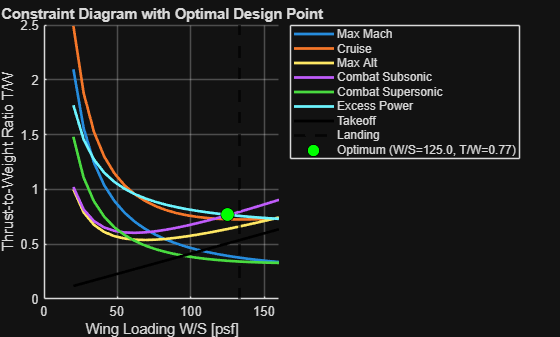


constraint_obj.plotConstraintDiagram(W_S, TW_table, T_Wto_takeoff, Wto_S_Landing, constraint_obj.optimal_WS, constraint_obj.min_TW, {constraints_table.Row{:}})

## Requirements

requirements_obj = Requirements(design);

## Run the project sizing class

% OLD COMMENT IGNORE THIS
% This calls the F16SizingLevel1 method directly. The method returns the
% converged W_TO. In the current class definition, results_table is assigned
% inside the method, but the class itself does not inherit handle, so the table
% may not persist outside the method depending on your inheritance tree.
% OLD COMMENT IGNORE THIS

% INITIALIZE THE SIZING OBJECT
sizing_obj       = F16SizingLevel1();


tol = 1e-3;
max_iteration = 40;
results = [];

LD_max = aero_obj.LD_max;
W_fixed = weight_obj.W_fixed;

W_S = constraint_obj.optimal_WS;
T_W = constraint_obj.min_TW;

W_TO = weight_obj.W_TO_guess;
S_ref = geometry_obj.mainwings.S_ref;

mission_data = mission_obj.missiondata;

for iteration = 1:max_iteration

     [weight_obj.total_fuel_used, weight_obj.fuel_fraction] = mission_obj.get_mission_fuel(propulsion_obj, mission_data, W_TO, LD_max);
     weight_obj.OEW = weight_obj.get_OEW(design.type, W_TO);
     weight_obj.OEW_frac = weight_obj.OEW/W_TO;

     W_TO_new = sizing_obj.compute_TOGW(weight_obj.OEW, weight_obj.total_fuel_used, W_fixed);
     difference = W_TO_new - W_TO;
     percent_diff = 100 * difference/W_TO;

     results(end+1, :) = [W_TO, W_fixed, weight_obj.fuel_fraction, weight_obj.OEW_frac, weight_obj.OEW, W_TO_new, difference, percent_diff, S_ref];

     if abs(difference) < tol
          break;
     end
     W_TO = W_TO_new;
     % T0 = T_W*W_TO;
     % S_ref = W_TO/W_S;

end
weight_obj.W_TO = W_TO;
sizing_obj.results_table = array2table(results, 'VariableNames', {'WTO', 'W_fixed', 'Fuel_fraction', 'Empty_weight_fraction', 'Empty_weight', 'WTO_new', 'Difference', 'Percent_Diff', 'S_ref'});
W_TO_final = W_TO_new;
sizing_output = sizing_obj.results_table;
disp(sizing_output);

% propulsion_obj.T0 = T0;

figure('Name', 'Level 1 Gross Weight Convergence');
plot(1:height(sizing_obj.results_table.WTO), sizing_obj.results_table.WTO, '-o', 'LineWidth', 1.5);
grid on;
xlabel('Iteration');
ylabel('W_{TO} [lbf]');
title('F-16A Level 1 Gross Weight Convergence');


## Plot closure error

figure('Name', 'Level 1 Closure Error');
plot(1:height(sizing_obj.results_table.WTO), sizing_obj.results_table.Percent_Diff, '-o', 'LineWidth', 1.5);
grid on;
xlabel('Iteration');
ylabel('Percent Difference [%]');
title('F-16A Level 1 Sizing Closure Error');

## Plot final weight breakdown

weightBreakdown = table( ...
     categorical(["OEW"; "Fuel Used"; "Fixed Weight"]), ...
     [sizing_output.Empty_weight(length(sizing_output.WTO)); ...
     sizing_output.Fuel_fraction(length(sizing_output.WTO)).*sizing_output.WTO(length(sizing_output.WTO)); ...
     sizing_output.W_fixed(length(sizing_output.WTO))], ...
     'VariableNames', {'Component', 'Weight_lbf'});

figure('Name', 'Level 1 Final Weight Breakdown');
bar(weightBreakdown.Component, weightBreakdown.Weight_lbf);
grid on;
ylabel('Weight [lbf]');
title('F-16A Level 1 Final Weight Breakdown');

## Save results into the AircraftDesign object

% % AircraftDesign is a handle class, so these assignments persist on the design
% % object during this MATLAB session.
%
design.WeightResults.Level1SizingTable = sizing_output;
design.WeightResults.W_TO              = sizing_output.WTO(length(sizing_output.WTO));
design.WeightResults.OEW               = sizing_output.Empty_weight(length(sizing_output.WTO));
design.WeightResults.FuelUsed          = sizing_output.Fuel_fraction(length(sizing_output.WTO)).*sizing_output.WTO(length(sizing_output.WTO));

design.AeroResults.Level1.LDmax         = aero_obj.LD_max;
design.AeroResults.Level1.AR_wetted     = aero_obj.AR_wet;
design.AeroResults.Level1.S_wet         = geometry_obj.design.S_wet;

% design.PropulsionResults.Level1.T0      = propulsion_obj.T0;
design.PropulsionResults.Level1.TSFC    = propulsion_obj.TSFC;